# Root Locus Design Example: Rack and Pinion

This script accompanies the Pinion-Rack example problem from the lecture with provided video and slides. The code is broken into sections for each step, delimited by %%.

## Design a P controller to achieve a target overshoot

Plant dynamics for pinion-rack

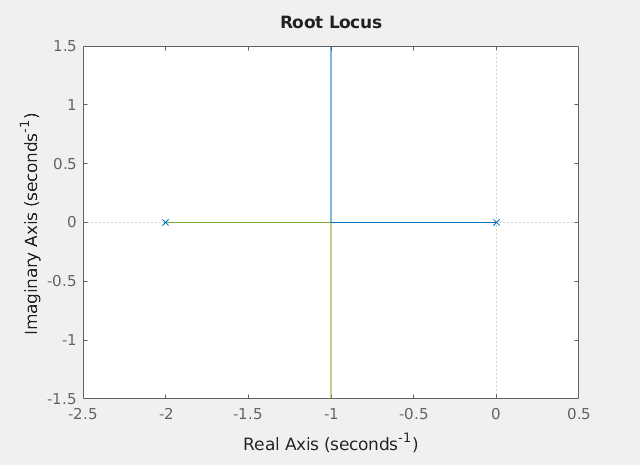

G = tf(.3162,[1 2 0]);

% Plot the root locus
figure(1);
clf()
rlocus(G);

## Express design goal in s-plane

Target oversoot is 4.3%. Find the corresponding damping ratio to locate the target pole placement in the s-plane.

os_target = 4.3;  % percent
zeta_target = -log(os_target/100) / sqrt(pi^2 +log(os_target/100)^2)

zeta_target = 0.7077

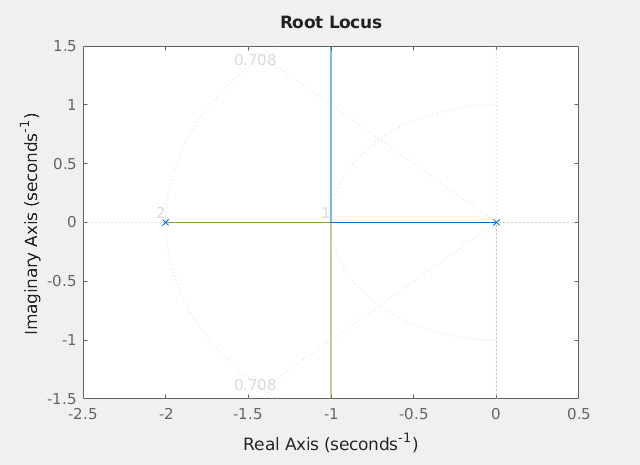


% Add grid-lines for target zeta value
sgrid(zeta_target,[1:3]);

## Find root locus gain (proportional gain) to place the CL poles at the target

Using the interactive "Data tips" tool we can select a value close to where the RL crosses the $\zeta = 0.707$ grid line. 

When using a live script (.mlx file), this opens the figure in a separate figure window so that we can use the interactive UI to choose a gain point on the RL.

set(gcf,'Visible','on')

We can use the interactive tool to select the location on the root locus that crosses the $\zeta = 0.707$ grid line:

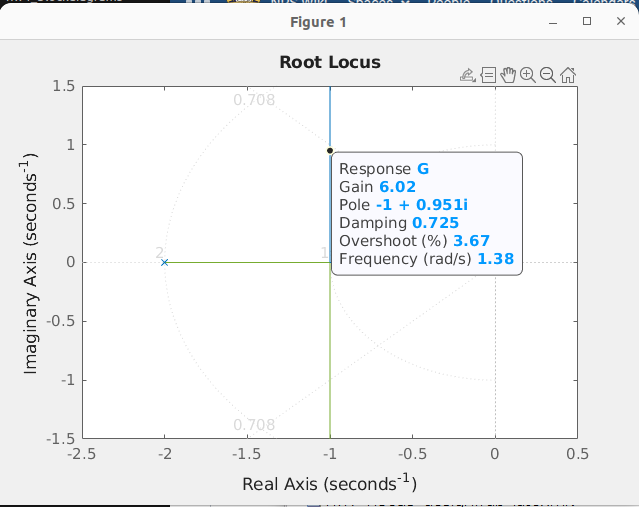

Here is a value found graphically for $\zeta = 0.707$

K = 6.02;

Optionally, we can check this by plotting the root locus for the specific gain value to verify the pole placement.

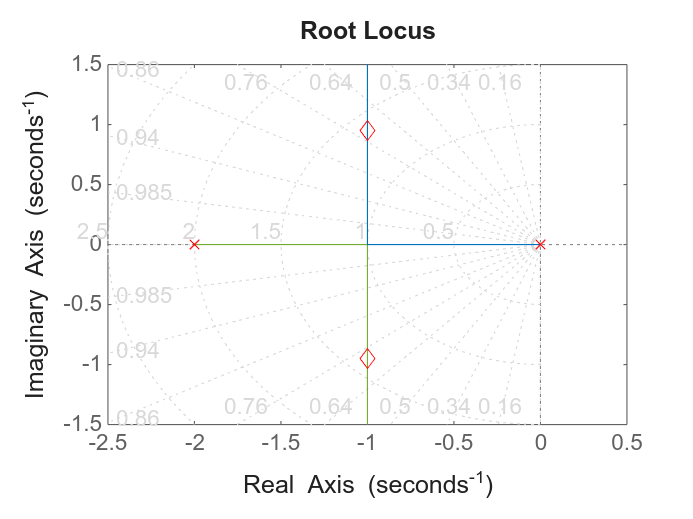

figure(2);
clf();
rlocus(G)
hold on
rlocus(G, K, 'rd')
sgrid(zeta_target,[1:3]);

## Verify that the closed-loop response matches the design target.

Close the loop

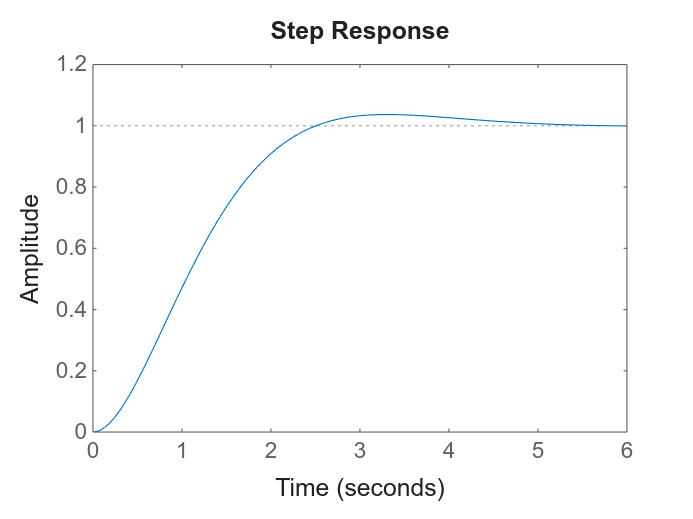

T = feedback(K*G,1);
figure(3);
clf();
step(T);

si_p = stepinfo(T)

si_p = struct with fields:
         RiseTime: 1.5978
    TransientTime: 4.2781
     SettlingTime: 4.2781
      SettlingMin: 0.9041
      SettlingMax: 1.0367
        Overshoot: 3.6693
       Undershoot: 0
             Peak: 1.0367
         PeakTime: 3.3157


The stepinfo command reports the closed loop overshoot as 3.7%

## PD Design

The new design goal want the same %OS with half the setting time. Our new design goal is to place the closed-loop poles at $s = -2 +/- 2j$.

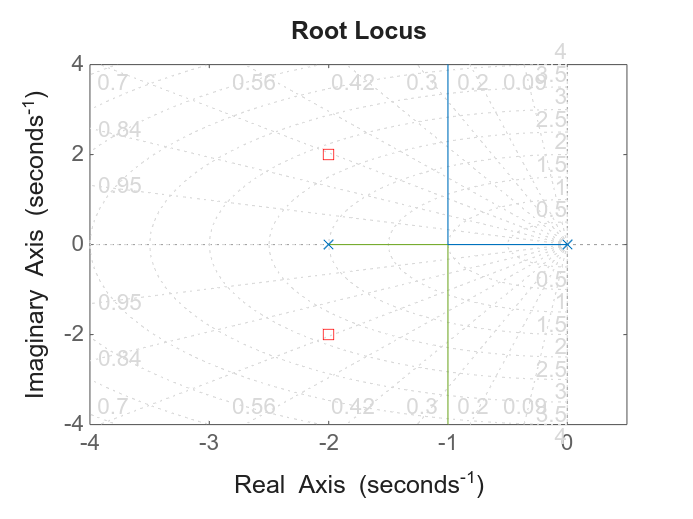

% Uncompensated plant with new design goal location.
figure(4);
clf();
rlocus(G);
% Overlay our s-plane pole placement target
hold on;
plot([-2, -2],[2, -2],'rs') % Design target
sgrid(0.707,[1:3])
xx = 4;
axis([-xx 0.5, -xx, xx])

## Add a PD compensator

We know that (1) PD is used to improve transient response and (2) that zeros tend to pull the RL toward them. We will add a PD compensator to the loop gain transfer function. For root locus design, PD compensation is equivalent to adding a zero to the loop transfer function. The design challenge is where to put the zero (z) so that the root locus goes through our target pole location. 

After some trial-and-error we find that this zero location drives the RL where we want it to be.

z= 4;
D = tf([1 z],1);  % PD Control

Overlay the root locus for the compensated system to see if it passes near our target.

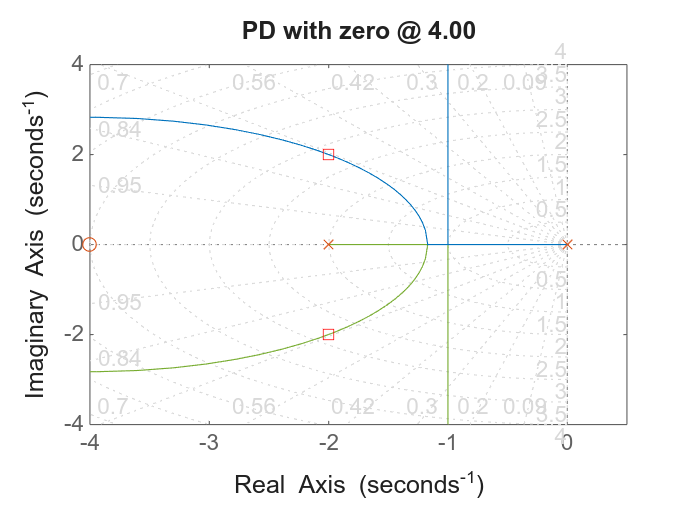

L = D*G;
rlocus(L);

title(sprintf('PD with zero @ %.2f',z));

## Choose PD gain value

Using the interactive tools, choose a gain value. We find that

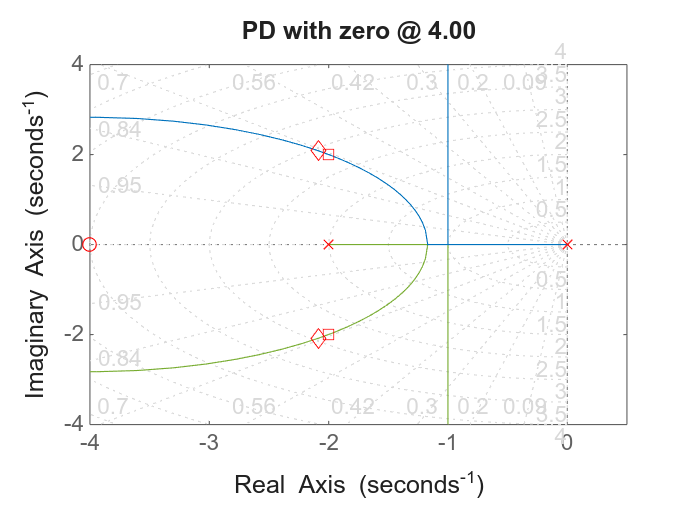

Kpd = 6.87;
% should put the closed-loop poles near the target
rlocus(L, Kpd, 'rd')

## Verify the closed loop response

Tpd = feedback(Kpd*L, 1)


Tpd =
 
     2.172 s + 8.689
  ---------------------
  s^2 + 4.172 s + 8.689
 
Continuous-time transfer function.
Model Properties



figure(6);
clf()
% P-only
step(T)
hold on
step(Tpd)
si_pd = stepinfo(Tpd)

si_pd = struct with fields:
         RiseTime: 0.5265
    TransientTime: 1.7809
     SettlingTime: 1.7809
      SettlingMin: 0.9009
      SettlingMax: 1.0696
        Overshoot: 6.9616
       Undershoot: 0
             Peak: 1.0696
         PeakTime: 1.1038


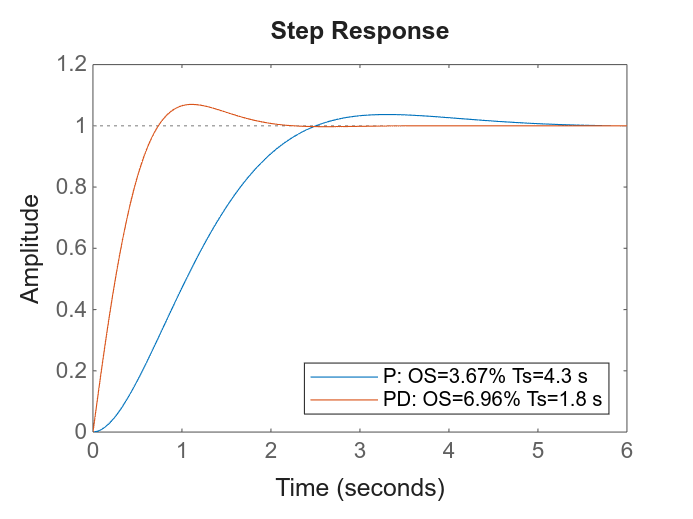

legend(sprintf("P: OS=%.2f%% Ts=%.1f s", si_p.Overshoot, si_p.SettlingTime), ...
    sprintf("PD: OS=%.2f%% Ts=%.1f s", si_pd.Overshoot, si_pd.SettlingTime), ...
    'Location','southeast')